# Diseño Intercambiador de Calor

## 0 Limpieza

clear
clc

## 1 Importación de Datos

Lectura de Datos

data=readtable("Intercambiador_Calor.csv")

data = 100×5 table
    Flujo_kg_s    Viscosidad_Pa_s    Area_m2    DeltaT_C    U_W_m2K
    __________    _______________    _______    ________    _______

      2.3766         0.0019699       47.758      50.593     190.15 
      3.7415         0.0028718       30.049      53.748      187.5 
     0.50051         0.0044867       46.202      44.421     159.65 
      1.8605         0.0021077        33.87      38.475     160.18 
      1.1604         0.0045884        22.55      18.049     137.07 
     0.91552         0.0033051        26.87      33.344     142.68 
      1.3382         0.0005712       32.194      27.259     154.07 
       2.055         0.0046825        29.73      21.252     149.89 
      2.2855          0.003609       46.678      39.626     182.39 
      2.9247          0.004988       46.343      25.613     18

## 2 Organización y Preprocesamiento

Acondicionamiento de Datos

Variables de estímulo

X = data{:, {'Flujo_kg_s', 'Viscosidad_Pa_s', 'Area_m2', 'DeltaT_C'}}

X =     2.3766    0.0020   47.7579   50.5929
    3.7415    0.0029   30.0494   53.7481
    0.5005    0.0045   46.2023   44.4207
    1.8605    0.0021   33.8705   38.4747
    1.1604    0.0046   22.5503   18.0486
    0.9155    0.0033   26.8696   33.3440
    1.3382    0.0006   32.1940   27.2586
    2.0550    0.0047   29.7297   21.2520
    2.2855    0.0036   46.6782   39.6256
    2.9247    0.0050   46.3430   25.6135


Variable de respuesta

Y = data.U_W_m2K

Y =   190.1477
  187.4979
  159.6520
  160.1783
  137.0710
  142.6755
  154.0653
  149.8930
  182.3935
  182.9109


Partición de datos para *Validación Cruzada*

cv = cvpartition(length(Y),'HoldOut',0.3); 
idxtrain=training(cv); % Va a cambiar aletoriamente entre diferentes corridas
idxtest=test(cv);     % Va a cambiar aletoriamente entre diferentes corridas
Xtrain = X(idxtrain, :);
Ytrain = Y(idxtrain, :);
Xtest = X(idxtest, :);
Ytest = Y(idxtest, :);

## 4 Creación del modelo

Entrenamiento

model = fitrensemble(Xtrain, Ytrain,'Method','Bag')

model =   RegressionBaggedEnsemble
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
          NumObservations: 70
               NumTrained: 100
                   Method: 'Bag'
             LearnerNames: {'Tree'}
     ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                  FitInfo: []
       FitInfoDescription: 'None'
           Regularization: []
                FResample: 1
                  Replace: 1
         UseObsForLearner: [70×100 logical]


  Properties, Methods


## 5 Evaluación del modelo

Validación

Ypred = predict(model, Xtest);
[b,bint,r,rint,stats] = regress(Ypred,[ones(size(Ytest)) Ytest]);
Yhat=Ypred-r

Yhat =   181.4823
  154.6405
  158.7214
  149.6004
  153.9447
  167.8020
  190.3535
  166.5284
  179.5024
  186.1056


Ordenamiento=[Ytest Yhat];
Ordenamiento=sortrows(Ordenamiento,1);
Ytest=Ordenamiento(:,1);
Yhat=Ordenamiento(:,2);

### Visualización de Predicción

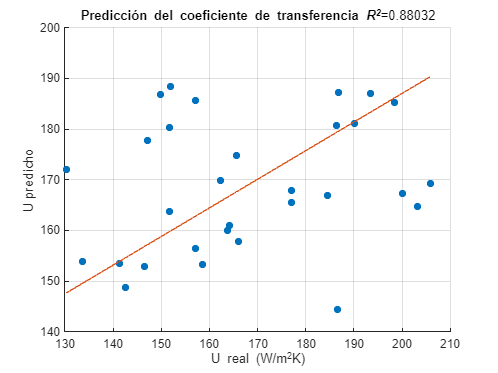

scatter(Ytest, Ypred, 'filled')
xlabel('U real (W/m^2K)')
ylabel('U predicho')
title(['Predicción del coeficiente de transferencia \itR^2\rm=' num2str(stats(1))])
grid on
hold on
plot(Ytest,Yhat)